# 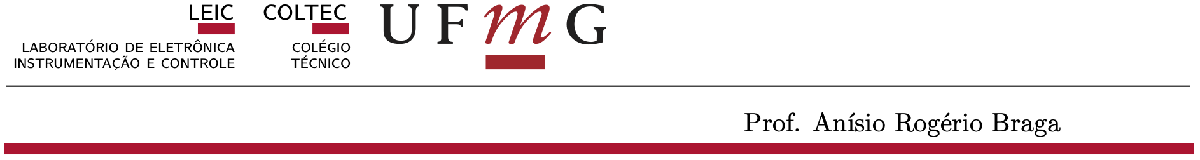

#  Estimação de modelo linear por partes de um sistema estático

**NAIEA 20.10rev2, ** A. R. Braga, COLTEC/UFMG

**Abstract**

Apresenta-se um procedimento para modelamento linear por partes de um sistema não linear a partir de dados experimentais. O procedimento é ilustrado com dados de uma curva experimental de um resistor em série com um LED.

## Introdução

O estudo e caracterização de componentes eletrônicos, sensores, atuadores e sistemas de instrumentação e controle de processos,  frequentemente, requer a estimação de inclinação ou ganho de sistemas lineares estáticos (frequência igual a zero). A figura 1 ilustra o arranjo experimental  para obter medidas de entrada $x$ e saída $y$.

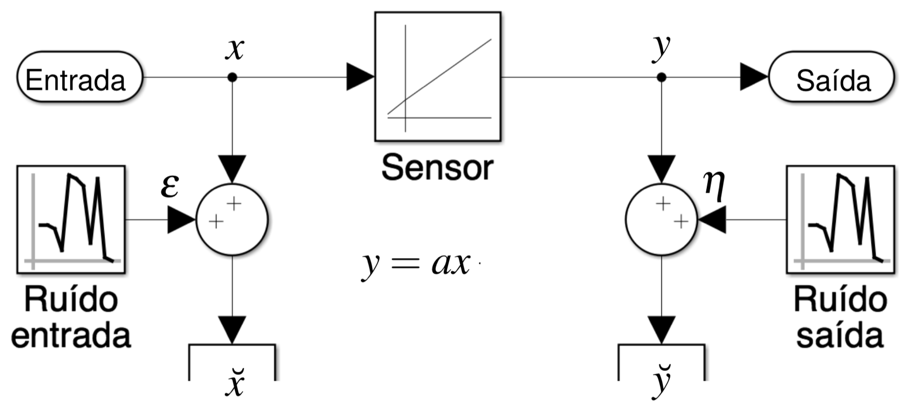

*Figura 1: Diagrama em blocos para caracterização estática de dispositivos mostrando medições de entrada e saída contaminadas por ruído.* 

A relação de transferência para um sistema linear é

$y= a \ x$.

Se apenas um par de pontos $(x_1, y_1)$ fosse usado, a inclinação $a$ seria facilmente estimada por 

$\hat{a} = \frac{\breve{y}_1 }{\breve{x}_1 }$,

em que $\hat{a}$ significa a inclinação ou coeficiente estimado e $(\breve{x}_1, \breve{y}_1)$ representa um par de pontos medidos para entrada e saída, respectivamente. 

Todavia, ao realizarmos experimentos obtemos vários pontos $(\breve{x}_i, \breve{y}_i)$, para $i= \{ \matrix{1, & 2, &, \ldots, N } \} $, pois testamos  diferentes valores para a  variável de entrada $x$ e medimos a resposta $y$ para verificar a relação de linearidade numa determina faixa. Obtemos assim dois vetores de dados


$$\textbf{x} =\matrix{[\breve{x}_1&\breve{x}_2 &\ldots & \breve{x}_N]}\\
\textbf{y} =\matrix{[\breve{y}_1& \breve{y}_2 &\ldots & \breve{y}_N]}\\
\hat{a} = \textbf{y}\cdot \textbf{x}^{-1}.$$


Como os dados são vetores de dimensão $N>1$não existe matriz inversa clássica, que requer que a dimensão matricial seja quadrada, i.e. $N \times N$. Entretanto, nos casos de necessidade de inverter matrizes não quadradas, existe uma solução ótima, obtida por meio de um algoritmo conhecido como Algoritmo dos Mínimos Quadrados, que viabiliza  inverter matrizes ou vetores não quadrados. Para tanto basta organizar os dados  usando vetores linha ou coluna. Usando a estrutura de vetor linha a função de inversão  implementada no Matlab executa a inversão usando o operador barra (`/`) como segue:

 $\hat{a} = \textbf{y}\cdot \textbf{x}^{-1}$, 

codificada como `a = y / x``.`

Se for utilizada uma estrutra de vetor coluna para os dados, 


$$\textbf{x} =\left[ \matrix{\breve{x}_1\cr \breve{x}_2 \cr \vdots \cr \breve{x}_N} \right];\quad
\textbf{y} =\left[ \matrix{\breve{y}_1\cr \breve{y}_2 \cr \vdots \cr \breve{y}_N} \right]$$


a ordem da divisão é permutada, i.e.

 $\hat{a} = \textbf{x}^{-1} \cdot  \textbf{y}$, 

que é codificada em Matlab usando o operador barra invertida, i.e. `a = x \ y ``.`

o comando `x\ `implementa a operação resultante do algoritmo de mínimos quadrados que resulta numa matriz pseudo inversa $X_p=(x^T*x)^{-1}x^T$.

## Experimento de caracterização estática de um dipolo não linear 

O experimento, como ilustrado na figura 1, consiste em excitar o circuito de um dipolo formado com um resistor R em série com um LED com um sinal de voltagem variando em pequenos incrementos formando degraus e medindo a corrente que circula através do dipolo.  

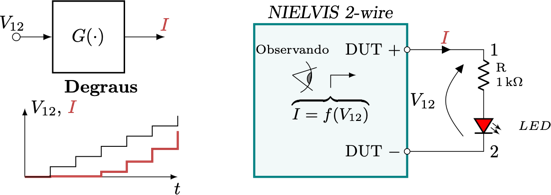

Figura 1: Diagrama esquemático do experimento de caracterização estática de um circuito série com Resistor e LED. 

### Exemplo 1: Caracterização estática de um dipolo formado por um LED vermelho em série com um resistor. 

Dados experimentais obtidos com o traçador de curva característica de dipolos elétricos *NIELVIS II 2-wire* são armazenados em uma matriz $\mathbf{z}$ como segue:

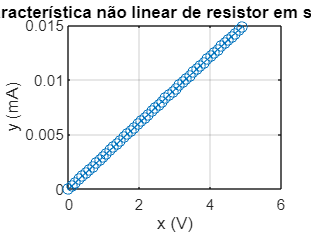

% z =[Voltagem(V) Corrente(mA)]
z=[0.003	0.021
0.101	0.316
0.197	0.609
0.299	0.916
0.399	1.219
0.490	1.495
0.592	1.802
0.689	2.095
0.790	2.401
0.896	2.722
0.983	2.986
1.081	3.280
1.182	3.586
1.279	3.879
1.381	4.191
1.472	4.466
1.573	4.772
1.668	5.058
1.768	5.359
1.868	5.660
1.964	5.952
2.060	6.243
2.161	6.549
2.263	6.857
2.359	7.147
2.461	7.457
2.552	7.734
2.653	8.037
2.749	8.328
2.848	8.630
2.951	8.939
3.047	9.231
3.143	9.522
3.244	9.827
3.339	10.115
3.441	10.422
3.536	10.711
3.632	11.000
3.732	11.301
3.828	11.591
3.928	11.895
4.029	12.200
4.125	12.491
4.220	12.777
4.321	13.082
4.423	13.393
4.522	13.691
4.620	13.987
4.708	14.254
4.816	14.580
4.914	14.877];

% Organizando os dados de entrada x e saída y em vetores coluna 
x = z(:,1); % voltagem de entrada organizada em vetor coluna
y = z(:,2)*1e-3; % corrente em mA organizada em vetor coluna
plot(x,y,'-o');grid
xlabel('x (V)')
ylabel('y (mA)')
title('Curva característica não linear de resistor em série com LED')

Analisando o resultado desenhado a partir dos dados $z = \{(x_1,y_1), (x_1,y_1), \quad \cdots, (x_N,y_N) \}, $notamos que os dados exibem duas regiões com comportamento linear por partes com inclinações bem discrepantes. Vamos separar os dados em dois conjuntos distintos, i.e.

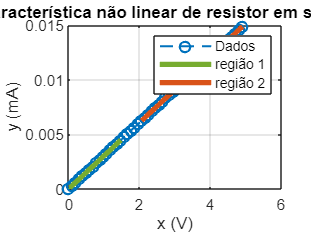

% selecionamos os dados para o intervalo x < 1.5
x1 = x(x<1.5);   
y1 = y(x<1.5); 
% selecionamos os dados para o intervalo x > 2 
x2 = x(x>2); 
y2 = y(x>2);
% Desenhamos os dados para visualizar o resultado
p = plot(x,y,'--o', x1,y1,x2,y2);grid
% Engrossamos os trechos para visualizar os trechos selecionados
p(1).LineWidth = 1.2;p(2).LineWidth = 3;p(3).LineWidth = 3;
p(2).Color = [0.4660 0.6740 0.1880]; % verde 
p(3).Color = [0.8500 0.3250 0.0980]; % orange
xlabel('x (V)')
ylabel('y (mA)')
title('Curva característica não linear de resistor em série com LED')

legend(["Dados", "região 1", "região 2"])

O próximo passo é estabelecer uma **nova origem** para os trechos de dados nos quais queremos calcular uma inclinação ou modelo linear.

y1

y1 =     0.0000
    0.0003
    0.0006
    0.0009
    0.0012
    0.0015
    0.0018
    0.0021
    0.0024
    0.0027


% Para o trecho x<1.5 observa-se y1 = 0 ==> r1 = infinito, valor obtido qualitativamente. 
r1 = inf

r1 = Inf

% Para o trecho x > 2 temos:
x2 = x2 - x2(1); % fazemos x_2 = 0 para estabelecer uma origem no subconjunto de dados x2.
y2 = y2 - y2(1); % fazemos y_2 = 0 para estabelecer uma origem no subconjunto de dados y2.
p = plot( x1,y1,'LineWidth', 2, 'Color', [0.4660 0.6740 0.1880]); grid
xlabel('x'); ylabel('y');
title('Curva característica linearizada')
p =  plot( x2,y2,'LineWidth', 2, 'Color',[0.8500 0.3250 0.0980]); grid

Error using matlab.graphics.axis.Axes/get
Operation terminated by the user.

Error in is2D>testOneAxes (line 34)
        camUp = get(ax,'CameraUpVector');

Error in is2D (line 23)
    retval = testOneAxes(ax);

Error in matlab.internal.editor.figure.FigureDataTransporter.getFigureDataEF

Error in matlab.internal.editor.figure.FigureDataTransporter.getFigureMe

xlabel('x'); ylabel('y')
title('Curva característica linearizada')

% a estimação do coeficiente é realizada automaticamente pelo Matlab usando
% o algoritmo de Mínimos Quadrados. Basta usar o operador \ e certificar-se
% que os vetores são vetores coluna!
g2 =  x2\y2  % inclinação = g = condutância em Siemens = [A]/[V]
r2 =  1/g2   % inverso da inclinação é a resistência dinâmica em Ohms
% Desenhamos as curvas com os dados medidos e o valor estimado par ao
% modleo linear y_est = a x
y_est = x2/r2;
plot(x2,y2,'o', x2,y_est,'-','LineWidth', 2); grid on
xlabel('x (V)'); ylabel('y (mA)')
title('Curva característica linearizada')

#### O eixo da origem pode ser colocado no meio de um segmento da função linear por partes? 

Sim. A escolha é do usuário. Entretanto recomenda-se que  o modelo linear seja obtido em torno do ponto quiescente desejado. A seguir ilustramos a estimação do coeficiente ou inclinação para um ponto quiescente situado no meio do conjunto de dados {x2;  y2}. 

N  = length(x2); i_origem = floor(N/2);
x2 = x2 - x2(i_origem); % fazemos x_2 = 0 para estabelecer uma origem no subconjunto de dados x2.
y2 = y2 - y2(i_origem); % fazemos y_2 = 0 para estabelecer uma origem no subconjunto de dados y2.
g2 =  x2\y2  % Siemens

y2_est = x2*g2; % valor estimado para as medidas usando o coeficiente estimado.

p =  plot( x2,y2,'o', x2,y2_est,'-','LineWidth', 2);grid
xlabel('x (V)'); ylabel('y(mA)')
title('Curva característica linearizada estimada')
ax = gca; % desenhando os eixo na origem
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
text(0.6,0.4,['y = ' num2str(1/r2) ' x'])
text(0.6,0.3,['R = ' num2str(r2) 'k\Omega'])
box off

#### Análise de erro de estimação

Um modelo linear estimado por meio do algoritmo de Mínimos Quadrados produz um erro com distribuição normal. Para avaliar este fato usamos o histograma do erro de estimação. O erro de estimação é calculado como


$$\epsilon =\mathbf{ \breve{y} } - \mathbf{  \hat{y}}, \\ 
\epsilon = \mathbf{ \breve{y} } - \hat{a} \cdot\mathbf{ \breve{x} }.
$$


erro = y2 - y2_est
histogram(erro)
DesvioPadrao = std(erro)

## Exercícios

A) Considerados os dados experimentais obtidos por meio de caracterização estática de um único LED, pede-se:  

- Obtenha um modelo linear por partes para os dados LED; 

- Utilizando os conceitos de energia, $E= h\cdot f$, em que $h$ é a constante de Planck e $f$é a frequência em Hertz, e  voltagem, $\text{Voltagem}=\frac{\text{Energia }\qquad  [J]} { \text{Carga elétrica } [C] }$),  qual é a cor mais provável do LED?

% Experimento de caracterização de um LED
% z = [Voltage(V)   Current(mA)]
z=[0.005	-0.007
0.100	-0.007
0.201	-0.007
0.696	-0.007
0.998	-0.007
1.203	-0.007
1.304	-0.007
1.398	-0.007
1.499	-0.007
1.600	-0.007
1.700	-0.007
1.800	-0.007
2.302	0.011
2.395	0.035
2.491	0.125
2.580	0.362
2.660	0.778
2.776	1.849
2.857	2.951
2.963	4.915
3.045	6.820
3.153	9.883
3.257	13.396
3.341	16.657
3.443	21.234
3.545	26.364
3.629	31.158
3.731	37.583]